clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


FPs = obj.MixedFP;
beh = obj.BehavTable;

session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");

HD = obj.HDSorted; HDPDF = obj.HDPDF; HDCDF = obj.HDCDF;
RT = obj.RTSorted; RTPDF = obj.RTPDF; RTCDF = obj.RTCDF;
MT = obj.MTSorted; MTPDF = obj.MTPDF; MTCDF = obj.MTCDF;


## Hold duration and reaction time

[~, hd_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), HD.Control, HD.Chemo);
hd_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), HD.Control, HD.Chemo);

[~, rt_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), RT.Control, RT.Chemo);
rt_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), RT.Control, RT.Chemo);


hd_categories = [0 .25 .5 2];
rt_categories = [.25 .5 2];

hd_p_chi2 = zeros(3, 2);
rt_p_chi2 = zeros(3, 2);
hd_p_chi2_sub = cell(3, 2);
rt_p_chi2_sub = cell(3, 2);
for fp = 1:3
    for p = 1:2
        [hd_p_chi2(fp, p), ~, hd_p_chi2_sub{fp, p}] = Chi2Test_Distr({HD.Control{fp, p}-FPs(fp), HD.Chemo{fp, p}-FPs(fp)}, hd_categories);
        [rt_p_chi2(fp, p), ~, rt_p_chi2_sub{fp, p}] = Chi2Test_Distr({RT.Control{fp, p}, RT.Chemo{fp, p}}, rt_categories);
    end
end

alpha = [.05 .01 .001];
alpha_hd = alpha ./ length(hd_categories);
alpha_rt = alpha ./ length(rt_categories);

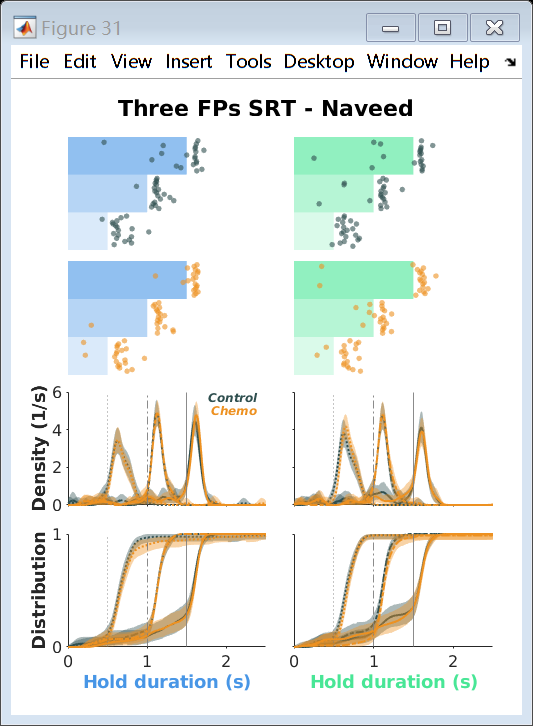


fig_hd = figure(31); clf(fig_hd);
set(fig_hd, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 9 11.2], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_hd, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

% show trials
DrawTrials(fig_hd, [1 6 7.5 4.2], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_hd, [1 1.2 7.5 4.5], [3.5 2], HDPDF, HDCDF);

fig_name = sprintf("Test_%s_HD_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_hd, fig_path+".pdf", 'ContentType', 'vector');

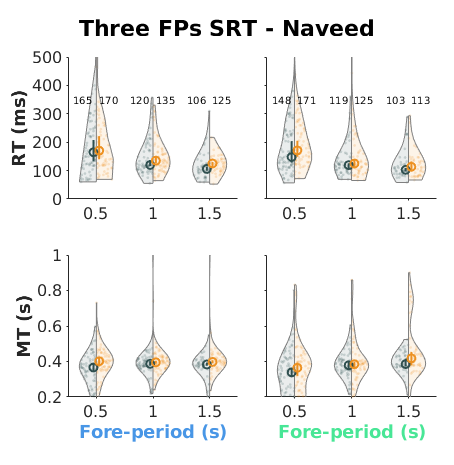

fig_response = figure(32); clf(fig_response);
set(fig_response, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 8.2], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_response, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

DrawViolin(fig_response, [1.2 1.2 6.5 6], [3 2.5], obj, RT, MT);

fig_name = sprintf("Test_%s_Response_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_response, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_response, fig_path+".pdf", 'ContentType', 'vector');

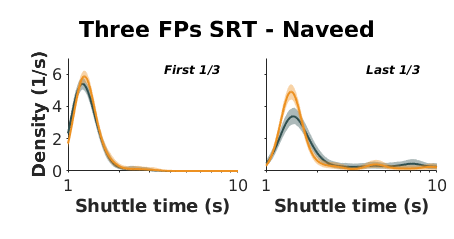

fig_st = figure(33); clf(fig_st);
set(fig_st, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 4.2], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_st, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

DrawShuttle(fig_st, [1.2 1.2 6.5 2.5], [3 2], obj.LogSTPDF);

fig_name = sprintf("Test_%s_ST_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_st, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_st, fig_path+".pdf", 'ContentType', 'vector');

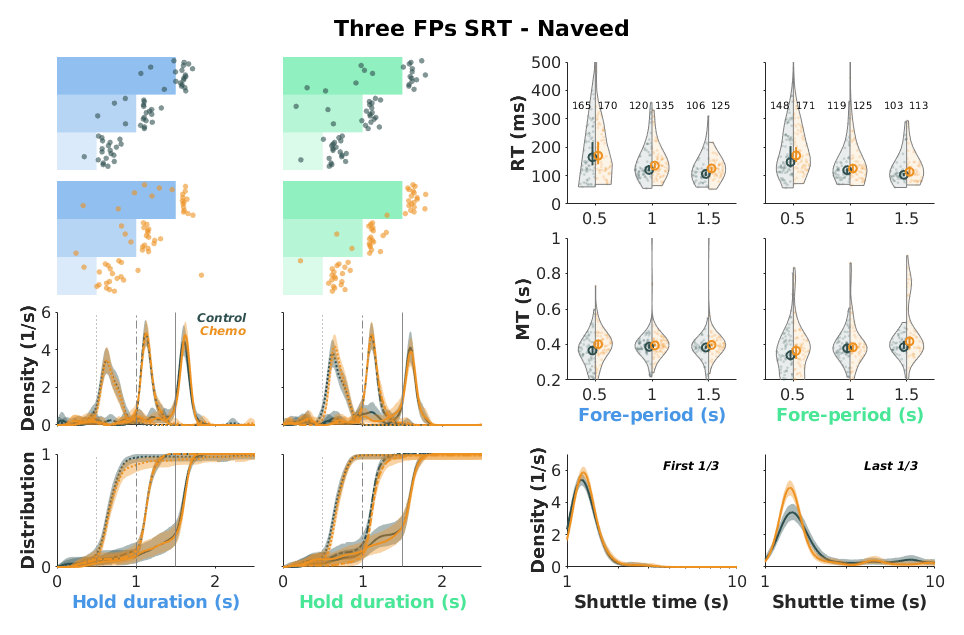

fig_total = figure(30); clf(fig_total);
set(fig_total, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 17 11.2], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_total, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

% show trials
DrawTrials(fig_total, [1 6 7.5 4.2], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_total, [1 1.2 7.5 4.5], [3.5 2], HDPDF, HDCDF);

% plot RT and MT violins
DrawViolin(fig_total, [10 4.5 6.5 5.6], [3 2.5], obj, RT, MT);

% plot first and last shuttle time
DrawShuttle(fig_total, [10 1.2 6.5 2.5], [3 2], obj.LogSTPDF);

fig_name = sprintf("Test_%s_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_total, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_total, fig_path+".pdf", 'ContentType', 'vector');

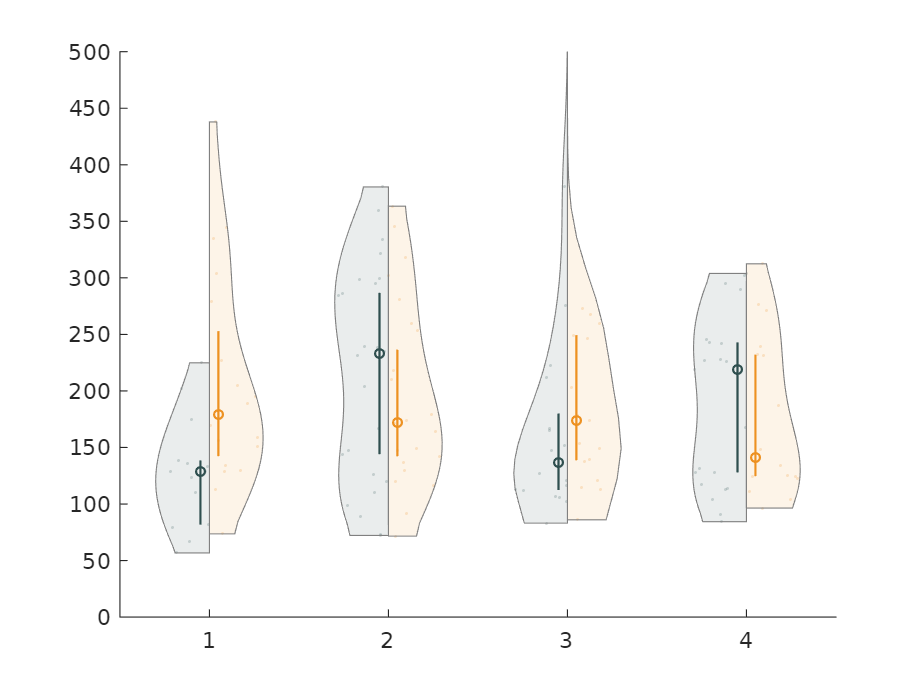

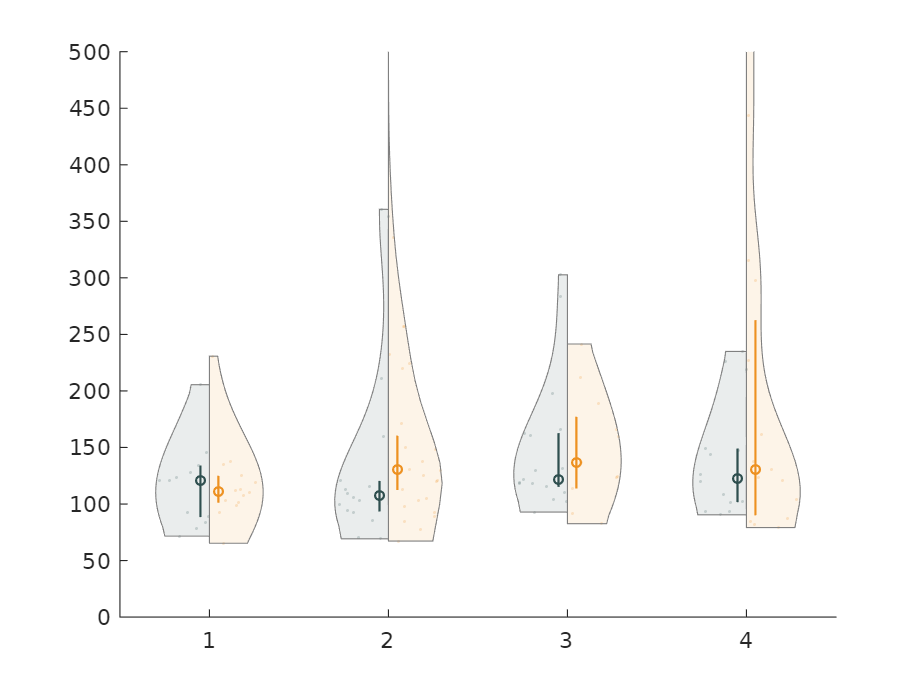

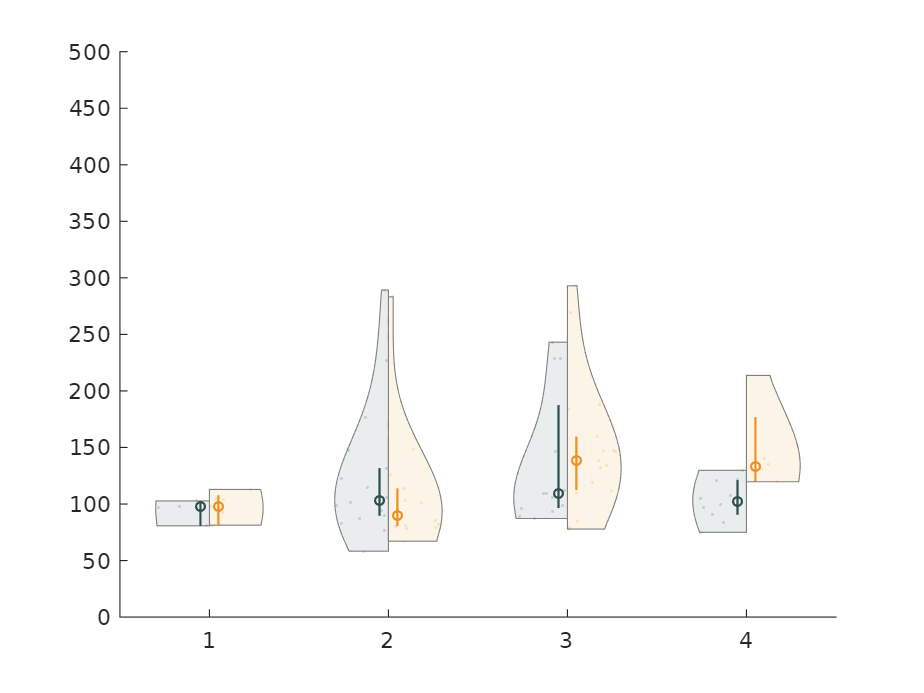

for i = 1:3
figure(); ax = axes(); hold on;
data_1 = cellfun(@(x) x{i,2}, obj.RTSorted.Session(obj.Label=="Control"), UniformOutput=false);
data_2 = cellfun(@(x) x{i,2}, obj.RTSorted.Session(obj.Label=="Chemo"), UniformOutput=false);

plot_violin_compare(ax, data_1, data_2, .05, 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1000);
ylim([0 500]);
end

function ax = DrawTrials(fig, pos, ax_sz, data)
%% Show trials
ax = cell(2,2);
% left control
x_now = pos(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_trials(ax{1,1}, data.Control(:,1), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortL, 'MarkerColor', GPSColor.Control, 'MarkerSize', 8);
set(ax{1,1}, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');
% left chemo
x_now = pos(1); y_now = pos(2);
ax{2,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_trials(ax{2,1}, data.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortL, 'MarkerColor', GPSColor.Treat, 'MarkerSize', 8);
set(ax{2,1}, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');
% right control
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_trials(ax{1,2}, data.Control(:,2), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortR, 'MarkerColor', GPSColor.Control, 'MarkerSize', 8);
set(ax{1,2}, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');
% right chemo
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2);
ax{2,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_trials(ax{2,2}, data.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortR, 'MarkerColor', GPSColor.Treat, 'MarkerSize', 8);
set(ax{2,2}, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');

drawnow();
end % DrawTrials

%%
function ax = DrawDistr(fig, pos, ax_sz, data_pdf, data_cdf)
%% Plot pdf and cdf
ax = cell(2,2);
ymax = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), data_pdf.Control, data_pdf.Chemo)));
ylim = ceil(ymax);
% plot prob density, left
x_now = pos(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{1,1}, data_pdf.Control(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax{1,1}, data_pdf.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
text(ax{1,1}, 2.4, .96*ylim, '\it{Control}', 'Fontweight', 'bold', 'FontSize', 6, 'Color', GPSColor.Control, 'HorizontalAlignment', 'right');
text(ax{1,1}, 2.4, .84*ylim, '\it{Chemo}', 'Fontweight', 'bold', 'FontSize', 6, 'Color', GPSColor.Treat, 'HorizontalAlignment', 'right');
ylabel(ax{1,1}, "Density (1/s)", 'FontWeight', 'bold');
set(ax{1,1}, 'XLim', [0 2.5], 'YLim', [0 ylim], 'XTickLabel', '');
% plot cumulative distribution, left
x_now = pos(1); y_now = pos(2);
ax{2,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{2,1}, data_cdf.Control(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax{2,1}, data_cdf.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
ylabel(ax{2,1}, "Distribution", 'FontWeight', 'bold');
xlabel(ax{2,1}, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortL);
set(ax{2,1}, 'XLim', [0 2.5], 'YLim', [0 1], 'YTick', [0 1]);
% plot prob density, right
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{1,2}, data_pdf.Control(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax{1,2}, data_pdf.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
set(ax{1,2}, 'XLim', [0 2.5], 'YLim', [0 ylim], 'XTickLabel', '', 'YTickLabel', '');
% plot cumulative distribution, right
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2);
ax{2,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{2,2}, data_cdf.Control(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax{2,2}, data_cdf.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
xlabel(ax{2,2}, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortR);
set(ax{2,2}, 'XLim', [0 2.5], 'YLim', [0 1], 'YTick', [0 1], 'YTickLabel', '');

drawnow();
end % DrawDistr

%%
function ax = DrawViolin(fig, pos, ax_sz, obj, data_rt, data_mt)
%% Plot violin comparations
ax = cell(2,2);
% reaction time, left
x_now = pos(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax{1,1}, data_rt.Control(:,1), data_rt.Chemo(:,1), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1000, 'Text', true);
ylabel(ax{1,1}, "RT (ms)", 'FontWeight', 'bold');
set(ax{1,1}, 'YLim', [0 500]);
% reaction time, right
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2)+pos(4)-ax_sz(2);
ax{1,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax{1,2}, data_rt.Control(:,2), data_rt.Chemo(:,2), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1000, 'Text', true);
set(ax{1,2}, 'YLim', [0 500], 'YTickLabel', '');
% movement time, left
x_now = pos(1); y_now = pos(2);
ax{2,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax{2,1}, data_mt.Control(:,1), data_mt.Chemo(:,1), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1, 'Text', false);
ylabel(ax{2,1}, "MT (s)", 'FontWeight', 'bold');
xlabel(ax{2,1}, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortL);
set(ax{2,1}, 'YLim', [.2 1]);
% movement time, right
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2);
ax{2,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax{2,2}, data_mt.Control(:,2), data_mt.Chemo(:,2), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1, 'Text', false);
xlabel(ax{2,2}, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortR);
set(ax{2,2}, 'YLim', [.2 1], 'YTickLabel', '');

end % DrawViolin

%%
function ax = DrawShuttle(fig, pos, ax_sz, data)
%% Plot shuttle time (first and last 1/3 trials)
st_pd_max = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), data.Control, data.Chemo)));
st_pd_ylim = ceil(st_pd_max);
ax = cell(1,2);
% first 1/3
x_now = pos(1); y_now = pos(2);
ax{1,1} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{1,1}, data.Control(1), ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', "-");
plot_distr(ax{1,1}, data.Chemo(1), ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', "-");
text(ax{1,1}, .9, .9*st_pd_ylim, '\it{First 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
xlabel(ax{1,1}, "Shuttle time (s)", 'FontWeight', 'bold');
ylabel(ax{1,1}, "Density (1/s)", 'FontWeight', 'bold');
set(ax{1,1}, 'YLim', [0 st_pd_ylim], 'XLim', [0 1], ...
    'XTick', log10(1:10), 'XTickLabel', ["1" repmat("", 1, 8) "10"], 'XTickLabelRotation', 0);
% last 1/3
x_now = pos(1)+pos(3)-ax_sz(1); y_now = pos(2);
ax{1,2} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax{1,2}, data.Control(end), ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', "-");
plot_distr(ax{1,2}, data.Chemo(end), ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', "-");
text(ax{1,2}, .9, .9*st_pd_ylim, '\it{Last 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
xlabel(ax{1,2}, "Shuttle time (s)", 'FontWeight', 'bold');
set(ax{1,2}, 'YLim', [0 st_pd_ylim], 'XLim', [0 1], ...
    'YTickLabel', '', 'XTick', log10(1:10), 'XTickLabel', ["1" repmat("", 1, 8) "10"], 'XTickLabelRotation', 0);

drawnow();
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function plot_trials(ax, data, varargin)

defaultColor = [0 0 0];
defaultSize = 16;
defaultNumShow = 20;
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addOptional(p,'n_show', defaultNumShow, @isnumeric);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'FaceColor', defaultColor);
addParameter(p,'MarkerColor', defaultColor);
addParameter(p,'MarkerSize', defaultSize);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
n_show = p.Results.n_show;
FP = p.Results.FP;
FaceColor = p.Results.FaceColor;
MarkerColor = p.Results.MarkerColor;
MarkerSize = p.Results.MarkerSize;

%
n_show = min([n_show min(cellfun(@(x) length(x), data))]);

for i=1:length(data)
    if FP(i)~=0
        fill(ax, [0 FP(i) FP(i) 0], [0 0 1 1]+i-1, 'r', ...
            'FaceColor', FaceColor, 'FaceAlpha', .6*FP(i)/max(FP), 'EdgeColor', 'none');
    end
    id_show = randperm(length(data{i}), n_show);
    scatter(ax, data{i}(id_show), linspace(.1, .9, n_show)+i-1, MarkerSize, "filled", ...
        "MarkerEdgeColor", "none", "MarkerFaceColor", MarkerColor, "MarkerFaceAlpha", .6);
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_distr(ax, data, varargin)

defaultColor = [0 0 0];
defaultLw = repmat(1.2, 1, length(data));
defaultLs = repmat("-", 1, length(data));
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'Color', defaultColor);
addParameter(p,'LineWidth', defaultLw, @isvector);
addParameter(p,'LineStyle', defaultLs, @isvector);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
FP = p.Results.FP;
Color = p.Results.Color;
LineWidth = p.Results.LineWidth;
LineStyle = p.Results.LineStyle;

if length(LineWidth)==1
    LineWidth = repmat(LineWidth, 1, length(data));
elseif length(LineWidth)~=length(data)
    error("Unmatched length between lw and data");
end
if length(LineStyle)==1
    LineStyle = repmat(LineStyle, 1, length(data));
elseif length(LineStyle)~=length(data)
    error("Unmatched length between ls and data");
end
%

for i=1:length(data)
    if FP(i)~=0
        xline(ax, FP(i), 'LineStyle', LineStyle(i), 'Color', [.5 .5 .5]);
    end
    if ~isempty(data{i}.ci)
        fill(ax, [data{i}.x flip(data{i}.x)], [data{i}.ci(1,:) flip(data{i}.ci(2,:))], 'r', ...
            'FaceColor', Color, 'FaceAlpha', .4, 'EdgeColor', 'none');
    end
    plot(ax, data{i}.x, data{i}.f, 'Color', Color, 'LineWidth', LineWidth(i), 'LineStyle', LineStyle(i));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_violin_compare(ax, datain_1, datain_2, band_width, varargin)

defaultCate = string(1:length(datain_1));
defaultColor = repmat({[0 0 0]}, 1, 2);
defaultScale = 1;

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'datain_1', @iscell);
addRequired(p,'datain_2', @iscell);
addRequired(p,'band_width', @isnumeric);
addParameter(p,'cate_name', defaultCate);
addParameter(p,'Color', defaultColor);
addParameter(p,'Scale', defaultScale);
addParameter(p,'Text', false);

parse(p, ax, datain_1, datain_2, band_width, varargin{:});

ax = p.Results.ax;
datain_1 = p.Results.datain_1;
datain_2 = p.Results.datain_2;
band_width = p.Results.band_width;
cate_name = p.Results.cate_name;
Color = p.Results.Color;
Scale = p.Results.Scale;
Text = p.Results.Text;

n_data_1 = max(cellfun(@length, datain_1));
n_data_2 = max(cellfun(@length, datain_2));
n_data = max([n_data_1 n_data_2]);

if length(n_data_1)~=length(n_data_2)
    error("input data dont match");
else
    n_cate = length(datain_1);
end

%
data_1 = nan(n_data, n_cate);
data_2 = nan(n_data, n_cate);

for i = 1:n_cate
    data_1(1:length(datain_1{i}), i) = Scale*datain_1{i};
    data_2(1:length(datain_2{i}), i) = Scale*datain_2{i};
end

data_med_ci_1 = bootci(1000, @(x) median(x, 'omitnan'), data_1);
data_med_ci_2 = bootci(1000, @(x) median(x, 'omitnan'), data_2);

data_med_1 = median(data_1, 'omitnan');
data_med_2 = median(data_2, 'omitnan');

%
axes(ax);
v = violinplot({data_2, data_1}, cate_name, ...
    'ViolinColor', Color([2 1]), 'ViolinAlpha', {.1, .1}, ...
    'BandWidth', Scale*band_width, 'MarkerSize', 2, ...
    'ShowMedian', false, 'ShowWhiskers', false, 'ShowBox', false);
xlim(ax, [.5 n_cate+.5]);

for i = 1:n_cate
    v(i).ScatterPlot.MarkerFaceAlpha = .2;
    v(i).ScatterPlot2.MarkerFaceAlpha = .2;

    scatter(ax, i-.05, data_med_1(i), 16, Color{1}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    scatter(ax, i+.05, data_med_2(i), 16, Color{2}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    plot(ax, [i-.05 i-.05], data_med_ci_1(:,i), 'Color', Color{1}, 'LineWidth', 1);
    plot(ax, [i+.05 i+.05], data_med_ci_2(:,i), 'Color', Color{2}, 'LineWidth', 1);

    if Text
        text(ax, i-.05, 350, sprintf('%.0f', data_med_1(i)), 'FontSize', 5, 'HorizontalAlignment', 'right');
        text(ax, i+.05, 350, sprintf('%.0f', data_med_2(i)), 'FontSize', 5, 'HorizontalAlignment', 'left');
    end
    set(ax, 'Box', 'off');
end

end
